rate = 48000;
intervalT = .5 * rate;

lfCut = 500;
nfft = 2^nextpow2(intervalT);

fd = load('1cup_freq.txt')

fd =    512
   511
   509
   509
   507
   505
   505
   501
   499
   494


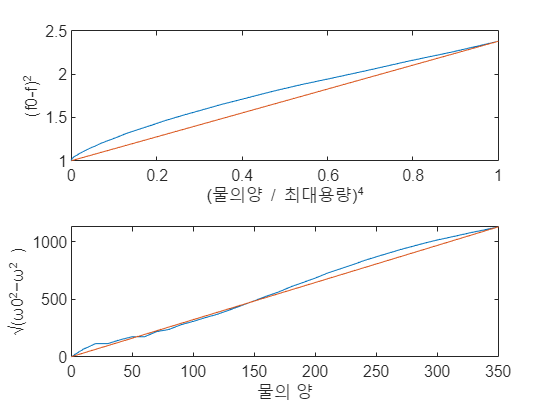


f = fd + lfCut;
f = f / nfft * rate;

X0 = 0:10:350; % 물의 양 

X = (X0/350).^4; % (물의 양 / 최대 용량)^4
Y = (f(1) ./ f).^2; % (f0 - f)^2

% w_0 = f(1) *  2 * pi;
% w = 2 * pi * f;
% Y3 = sqrt(w_0^2 - w.^2);

Y2 = sqrt(f(1).^2 - f.^2);

clf
start = 1;
last = length(X) - 0;


subplot 211
plot(X(start:last), Y(start:last))
hold on
plot(X([start, last]), Y([start, last]))
xlabel('(물의양 / 최대용량)^4')
ylabel('(f0-f)^2')


subplot 212
plot(X0(start:last), Y2(start:last))
hold on
plot(X0([start, last]), Y2([start, last]))
xlabel('물의 양')
ylabel('√(ω0^2−ω^2 )')

X = X.';
% Y = Y.';
% 
save 1cupX X
save 1cupY Y


% %%
X0 = X0.';
% Y2 = Y2.';
% 
save 1cupX0 X0
save 1cupY2 Y2